#              Computational Electromagnetics 

##                                             Hw3

                 Mohammadreza Arani         :::::::::::::         810100511

                                                            1401/08/18          

### Q-3.24:

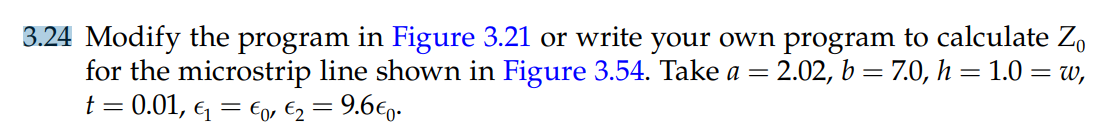

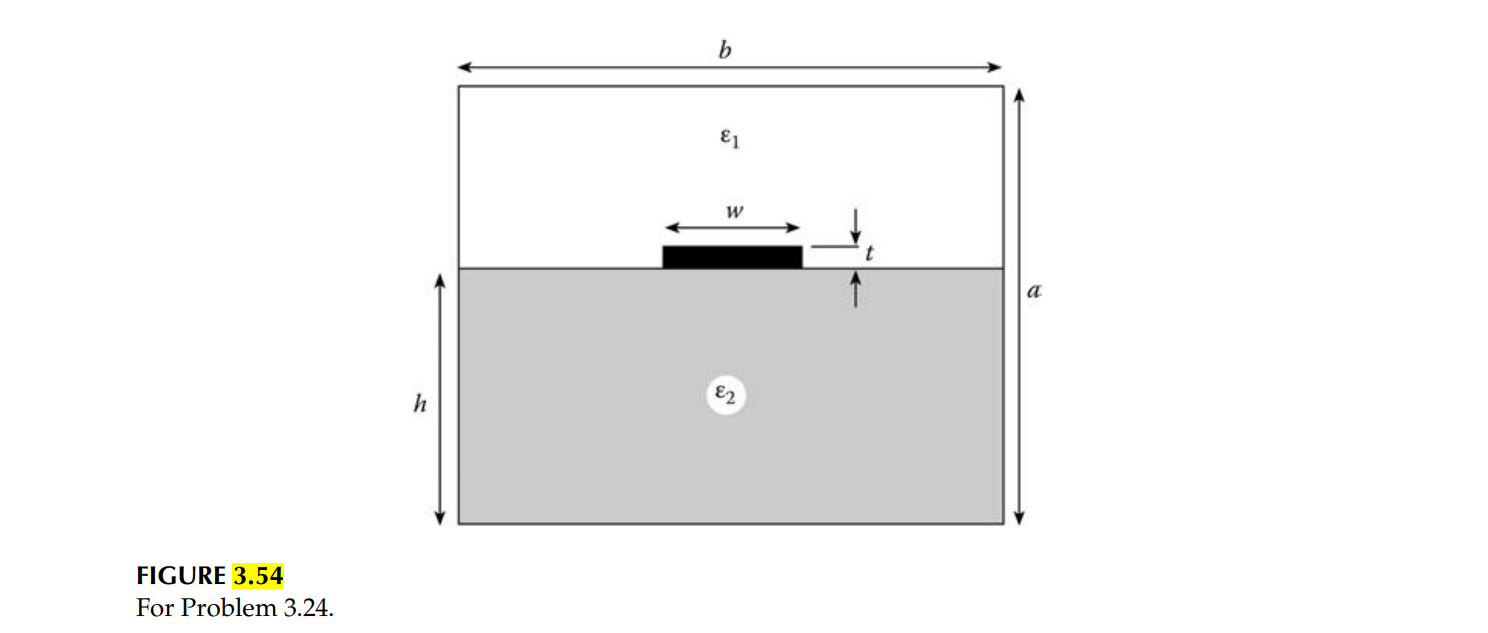

we can use symmetry in this problem and consider the right half of this geometry -->

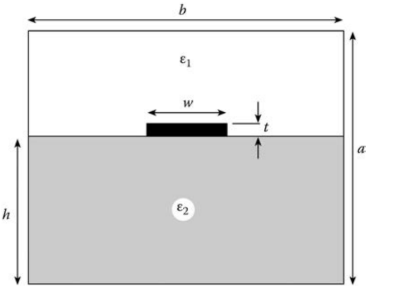

                                               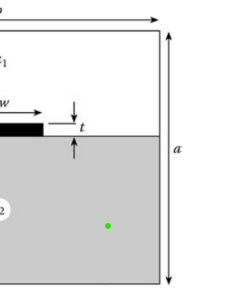

clear; clc;
eps0 = 8.854178128e-12 ; % Vacuum Permitivity   [F.m-1]
a=2.02;  
b=7.0; 
h=1.0; 
w = h; 


t=0.01;  

eps1 = eps0; 
eps2 = 9.6*eps0;


H = 0.001; 
NT = 30000;

A  = a; B=b/2; D=h; W=w/2;

ER = 9.6 ;
EO = 8.81e-12;
U = 3.0e+8;

NX  = round(A/H);
NY  = round(B/H);
ND  = round(D/H);
NW  = round(W/H);
VD  = 100.0;


## Calculate charge with and without DIELECTRIC



ERR = 1.0; % without DIELECTRIC
for L=1:2
    E1 = EO;
    E2 = EO*ERR;

% INITIALIZATION

    V = zeros(NX+2,NY+2);

% Set POTENTIAL ON INNER CONDUCTOR (FIXED NODES) EQUAL TO VD
    V(2:NW+1,ND+2)  =VD; % On the strip line --> the conductor

% CALCULATE POTENTIAL AT FREE NODES  <MAIN Part of the Programm>

    P1 = E1/(2*(E1+E2));
    P2 = E2/(2*(E1+E2));
    for K=1:NT
        for I=0:NX-1
            for J=0:NY-1
                if( (J==ND)&(I<NW)  )
                    % do nothing
                elseif (J==ND) % The Line Between 2 materials
                    % IMPOSE BOUNDARY Condition at the Interface --> the
                    % Line between 2 materials (DIELECTRICS)
                    V(I+2,J+2) = 0.25*( V(I+3,J+2) +  V(I+1,J+2)   )  + P1*V(I+2,J+3) + P2*V(I+2,J+1); % This Formula is obtained by Hand Calculations in Eq. 3.53 --> printed below

                elseif (I==0) % The Left Side --> Symmetry --> rond/rond x V = 0 --> 
                    % IMPOSE Symmetry COndition Along with Y-AXIS
                    V(I+2,J+2) = ( 2*V(I+3,J+2) + V(I+2,J+3) + V(I+2,J+1)   )/4.0;
                %elseif (J==0)
                   % IMPOSE BOUNDARY Condition at the Interface of E2 and
                   % the PEC wall
                   % V(I+2,J+2) = ( V(I+3,J+2) + V(I+1,J+2) + V(I+2,J+3)   )/4.0;
                else 
                    V(I+2,J+2) = (  V(I+3,J+2) + V(I+1,J+2) + V(I+2,J+3) + V(I+2,J+1) )/4.0;
                end
            end
        end
        % ANimation of Calculation
%         figure(1);
%         imagesc(V);
%         colorbar;
%         title([num2str(K),'/' , num2str(NT) ])
%         drawnow


    end


% Now Calculate the TOTAL CHARGE ENCLOSED IN A Rectangular Path Surrounding the Inner CONDUCTOR:
    IOUT = round((NX+NW)/2) ;
    JOUT = round((NY+ND)/2) ;
% SUM Potential on Inner and Outer LOOPS:
    for K=1:2
        SUM = E1* sum( V(3:IOUT+1 , JOUT+2)  )  + E1*V(2,JOUT+2)/2 ; % %E2*V(IOUT+2,2)/2; --> For symmetry Matter
        for J=round((ND)/2):JOUT-1
            if(J<ND)
                SUM =SUM + E2*V(IOUT+2,J+2);
            elseif (J==ND)
                SUM = SUM + (E1+E2)*V(IOUT+2,J+2)/2;
            else 
                SUM = SUM + E1*V(IOUT+2,J+2);
            end
        end

        if (K==2)
        SUM =SUM + sum(E2*V(3:IOUT+2,round((ND+2)/2)+1))  + E2/2*V(2,round((ND+2)/2)+1) ;
        else
        SUM =SUM + sum(E2*V(3:IOUT+2,round((ND+2)/2)))  + E2/2*V(2,round((ND+2)/2)) ;
        end

        if K==1
            SV(1) = SUM;
            V_C0 = V;
        end
        IOUT = IOUT -1;
        JOUT = JOUT -1;
    end
    SUM  = SUM + 2.0* E1* V(IOUT+2,JOUT+2);
    SV(2) =     SUM;
    Q(L)  = abs(SV(1) - SV(2) ); % Charge
    ERR = ER;
    
 end

 % Calculate the Z0:
    C0 = 2.0*Q(1)/VD ;
    C1 = 2.0*Q(2)/VD;
    Z0 = 1.0/( U*sqrt(C0*C1) );

    disp([H,NT,Z0]);

   1.0e+04 *

    0.0000    3.0000    0.1678



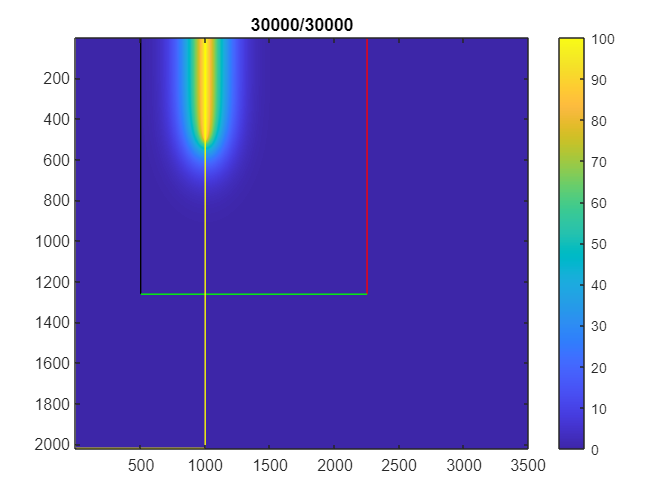

save("V_"+NT+"_H_"+H+"_12_Nov.mat");
    
IOUT = round((NX+NW)/2) ;
JOUT = round((NY+ND)/2) ;

figure(2);
imagesc(V);
colorbar;
title([num2str(NT),'/' , num2str(NT) ])
hold on

line( [JOUT+2,JOUT+2],[2,IOUT+2], 'Color', 'r');
line([(ND+2)/2,(ND+2)/2], [2,IOUT+2], 'Color', 'black');
line([(ND+2)/2,JOUT+2], [IOUT+2,IOUT+2], 'Color', 'g');

% line( [JOUT+1,JOUT+1],[2,IOUT+1], 'Color', 'g');
% line([(ND-2)/2,(ND-2)/2], [2,IOUT+1], 'Color', 'b');
% line([(ND-2)/2,JOUT+1], [IOUT+1,IOUT+1], 'Color', 'r');


% Inside The Di-Electric
line([2,ND],[NX,NX], 'Color', 'y');
line( [ND,ND],[NX,2], 'Color', 'y');
hold on
plot(V(2,JOUT+2),'r')

## New Q Line:

% SUM Potential on Inner and Outer LOOPS:

    SUM1 = E1* sum( V(2:IOUT+2,JOUT+2)  )  ;%+ E1*V(2,JOUT+2)/2 + E2*V(IOUT+2,2)/2;
    for J=round(ND-2)/2:JOUT+2
        if(J<ND)
            SUM1 =SUM1 + E2*V(IOUT+2,J);  % A Parallel Line along Y-Axis from The bottom up.
        else
            SUM1 =SUM1 + E1*V(IOUT+2,J);  % A Parallel Line along Y-Axis from The bottom up.
        end
    end

    %SUM1  = SUM1 + 2.0* E1* V(IOUT+2,JOUT+2);  % Corner Point
    SUM2  = E2* sum( V(2:IOUT+2 , round((ND-2)/2))  ); % + E1*V(2,Nb+2)/2 + E1*V(Na+2,2)/2;
%     for J=1:Nb+2            
%             SUM2 =SUM2 + E1*V(Na+2,J+2);  % A Parallel Line along Y-Axis from The bottom up.
%     end
    SUM2  = SUM2 + 2.0* E1* V(IOUT+2,JOUT+2);  % Corner Point

    Q2 = abs(SUM1 - SUM2 );

    V_C1 = V;
    V = V_C0;
% SUM Potential on Inner and Outer LOOPS:
    
    SUM1 = E1* sum( V(2:IOUT+2,JOUT+2)  )  ;%+ E1*V(2,JOUT+2)/2 + E2*V(IOUT+2,2)/2;
    for J=round(ND-2)/2:JOUT+2
        if(J<ND)
            SUM1 =SUM1 + E2*V(IOUT+2,J);  % A Parallel Line along Y-Axis from The bottom up.
        else
            SUM1 =SUM1 + E1*V(IOUT+2,J);  % A Parallel Line along Y-Axis from The bottom up.
        end
    end

    %SUM1  = SUM1 + 2.0* E1* V(IOUT+2,JOUT+2);  % Corner Point
    SUM2  = E2* sum( V(2:IOUT+2 , round((ND-2)/2))  ); % + E1*V(2,Nb+2)/2 + E1*V(Na+2,2)/2;
%     for J=1:Nb+2            
%             SUM2 =SUM2 + E1*V(Na+2,J+2);  % A Parallel Line along Y-Axis from The bottom up.
%     end
    SUM2  = SUM2 + 2.0* E1* V(IOUT+2,JOUT+2);  % Corner Point

    Q1 = abs(SUM1 - SUM2 );

  % Calculate the Z0:
    C0_2 = 4.0*Q1/VD ;  % *4  --> Due to Symmetry
    C1_2 = 4.0*Q2/VD;
    Z0_method2 = 1/( U*sqrt(C1*C0) );
    disp(Z0_method2) % The Impedance is Equal to:  ---> Which is very close to  43 ohm!

   1.6780e+03



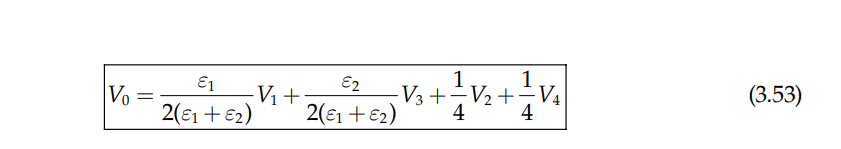

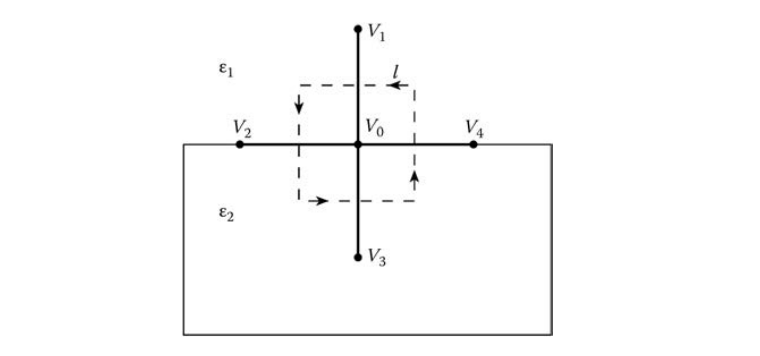

And for calculation of Charges enclosed in a rectangular shape:

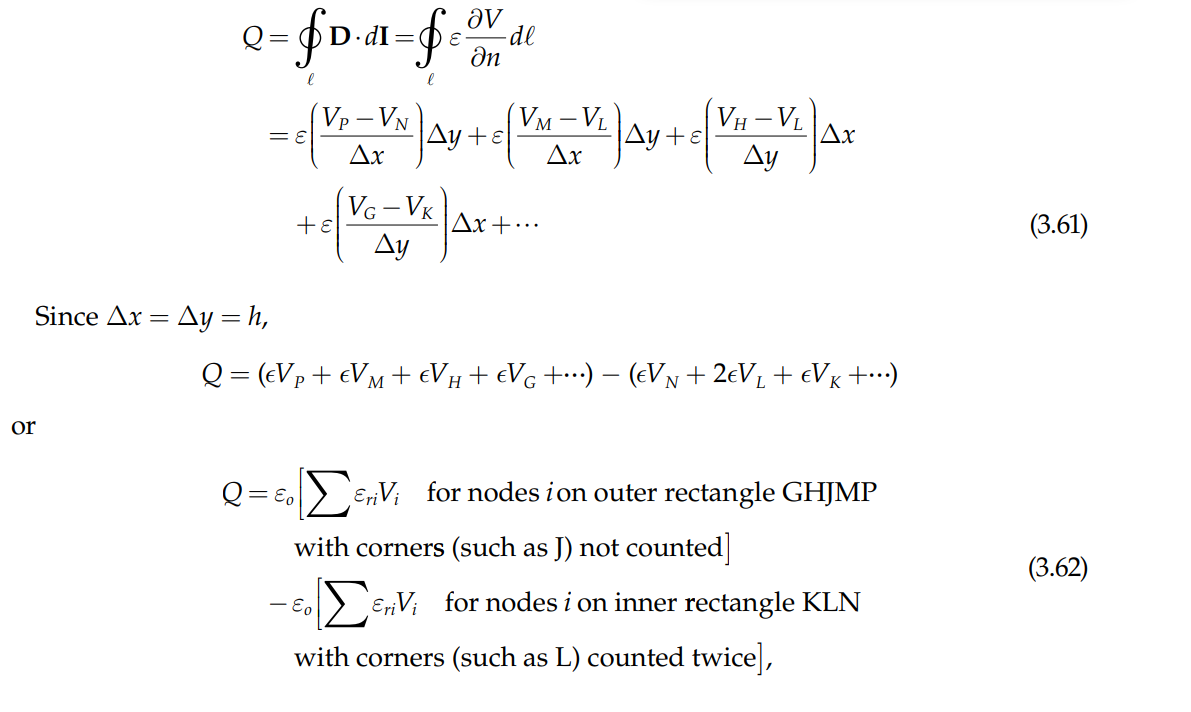

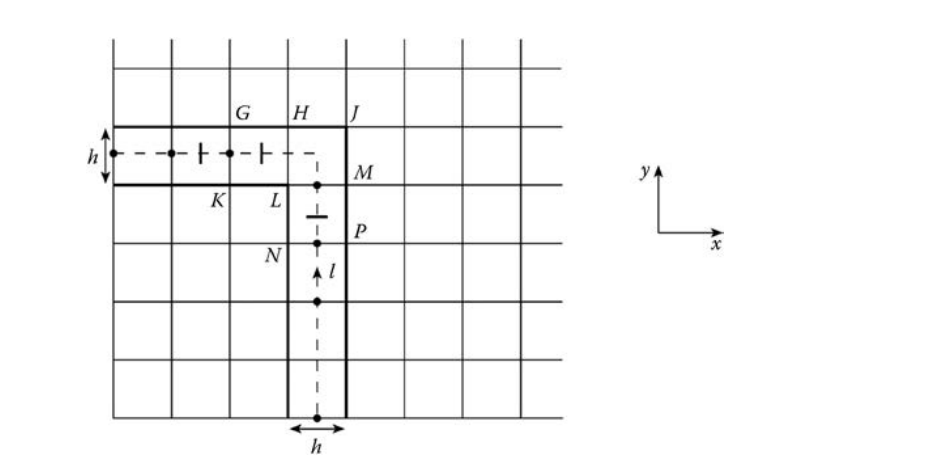

## Convergence:

Although, we did everything to reach the correct answer which is 43 ohm, we are not satisfied with results!  --> Convergence never happend! --> Tried debugging the code but failed --> 

Step 1:

H =     0.1         0.1                 0.01                 0.01               0.01               0.01                   0.001                    0.001

NT = 1000       5000             1000                 5000              10000            30000               10000                    30000

Z0 =   56.15    56.1581         145.6462          64.5268         56.9608        53.2661           5523000                1678

% My Code Did not Converge Properly! --> a  partial COnvergence can be
% observed --> maybe with increase in NT we face better results!




